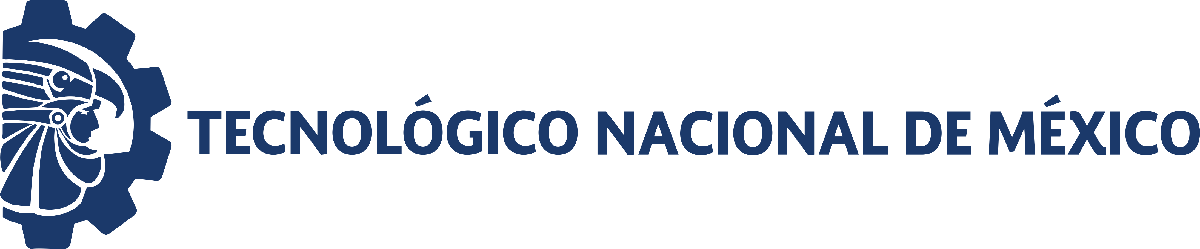                                 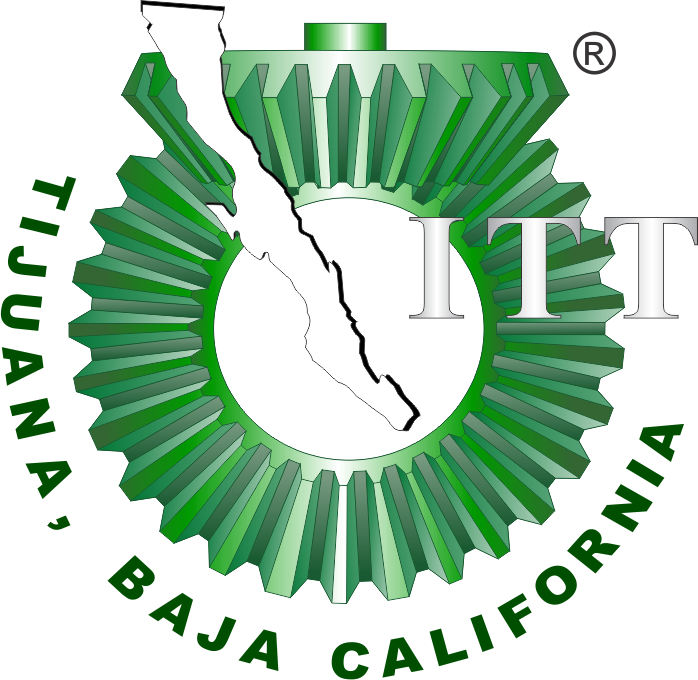

# Práctica tres: Sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

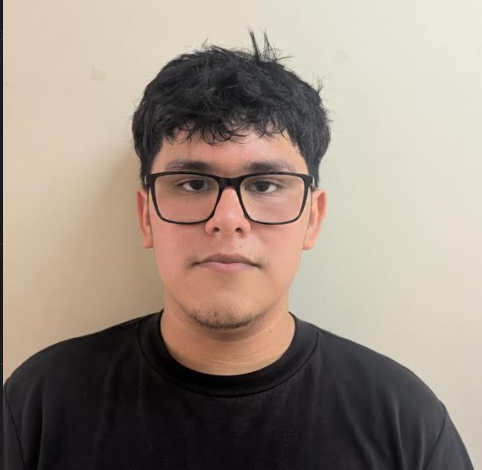

Nombre del alumno: Marco Antonio Garcia Montilla

Número de control: 22211756

Correo institucional: l22211756**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

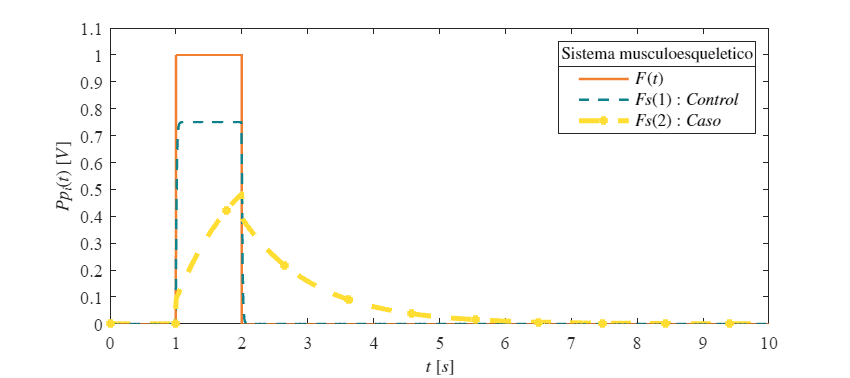

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistemaP2';
open_system(file);
parameters.StopTime=tend;
parameters.Solver = 'ode23t';
parameters.MaxStep='1E-3';
x = sim(file,parameters);
plotsignals(x.t,x.F,x.Fs1,x.Fs2)

## Datos de la simulación 2da gráfica

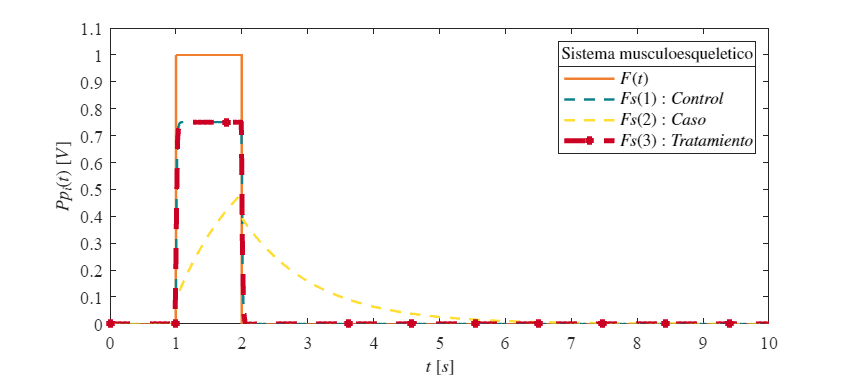


x2 = sim(file,parameters);
plotsignals2(x.t,x.F,x.Fs1,x.Fs2,x.Fs3)

## Función:Respuesta a las señales

function plotsignals(t,F,Fs1,Fs2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeter','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on;grid off; box on;
    mycolors =[240,128,48;
                15,130,140;
                255,221,51;
                204,0,34;
                143,163,30;
                107,36,12]/255;
    colororder(mycolors)

    p = plot(t,F,'-',t,Fs1,'--',t,Fs2,'--+',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',3);
    L = legend('$F(t)$','$Fs(1):Control$','$Fs(2):Caso$');
    set(L,'Interpreter','Latex','FontSize',10);
    title(L,'Sistema musculoesqueletico','FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    ylim([0,1.1]); yticks(-0.1:0.1:1.1);

    exportgraphics(gcf,['Sistema Musculoesqueletico','.pdf'],'ContentType','vector')
    exportgraphics(gcf,['Sistema Musculoesqueletico','.png'],'ContentType','vector')
end

## Función:Respuesta a las señales 2da

function plotsignals2(t,F,Fs1,Fs2,Fs3)
    set(figure(),'Color','w')
    set(gcf,'units','centimeter','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on;grid off; box on;
    mycolors =[240,128,48;
                15,130,140;
                255,221,51;
                204,0,34;
                143,163,30;
                107,36,12]/255;
    colororder(mycolors)

    p = plot(t,F,'-',t,Fs1,'--',t,Fs2,'--',t,Fs3,'--+',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(4),'LineWidth',3);
    L = legend('$F(t)$','$Fs(1):Control$','$Fs(2):Caso$','$Fs(3): Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10);
    title(L,'Sistema musculoesqueletico','FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

        xlim([0,10]); xticks(0:1:10);
    ylim([0,1.1]); yticks(-0.1:0.1:1.1);

    exportgraphics(gcf,['Sistema Musculoesqueletico PID','.pdf'],'ContentType','vector')
    exportgraphics(gcf,['Sistema Musculoesqueletico PID','.png'],'ContentType','vector')
end